# PLACCI analysis

Tim Sui, Oct 29, 2026

addpath(genpath('./'))

Be reminded to put `bfmatlab` folder containing `bioformat` package under the path!!

## Scan through microscopy images

paths = dir(fullfile('Managed', '*.czi'));
paths = {paths.name}';
paths([11,18,23,39]) = [];

phaseStat = [];
cellcount = [];
for i = 1:length(paths)
    dire = paths{i};
    Idx = PLACCI_Analysis(['Managed/', dire]);
    phaseStat = [phaseStat; [sum(Idx == 1), sum(Idx == 2), sum(Idx == 3)]];
    cellcount = [cellcount; length(Idx)];
end

2026-11-02T17:21:22.826864Z main WARN Unknown DetectorType value 'GaAsP-PMT' will be stored as "Other"
2026-11-02T17:21:22.830366Z main WARN Unknown DetectorType value 'Multialkali-PMT' will be stored as "Other"
Reading series #1
    ...
2026-11-02T17:21:25.970922Z main WARN Unknown DetectorType value 'GaAsP-PMT' will be stored as "Other"
2026-11-02T17:21:25.975937Z main WARN Unknown DetectorType value 'Multialkali-PMT' will be stored as "Other"
Reading series #1
    ...
2026-11-02T17:21:28.965184Z main WARN Unknown DetectorType value 'GaAsP-PMT' will be stored as "Other"
2026-11-02T17:21:28.965941Z main WARN Unknown DetectorType value 'Multialkali-PMT' will be stored as "Other"
Reading series #1
    ...
2026-11-02T17:21:31.928003Z main WARN Unknown DetectorType value 'GaAsP-PMT' will be stored as "Other"
2026-11-02T17:21:31.928698Z main WARN Unknown DetectorType value 'Multialkali-PMT' will be stored as "Other"
Reading series #1
    ...
2026-11-02T17:21:35.003216Z main WARN Unknown De


phaseStat = phaseStat(:, [3,1,2]);

## Plot graphs

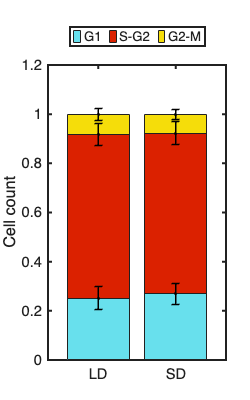

phaseStat = phaseStat./sum(phaseStat, 2);
phasebar = [mean(phaseStat(1:18, :)) ; mean(phaseStat(19:36,:))];
phasesd = [std(phaseStat(1:18, :)) ; std(phaseStat(19:36,:))];

a = figure; hold on;
b = bar(phasebar, 'stacked');
b(2).FaceColor = [219 33 0]./255;
b(3).FaceColor = [245 221 10]./255;
b(1).FaceColor = [104 224 237]./255;

xlim([0.35, 2.65])
xticks([1,2])
xticklabels({'LD', 'SD'})
errorbar(1:2, phasebar(:,1), phasesd(:,1), 'k.', 'LineWidth', 1.2);
errorbar(1:2, phasebar(:,1)+phasebar(:,2), phasesd(:,2), 'k.', 'LineWidth', 1.2);
errorbar(1:2, [1,1], phasesd(:,3), 'k.', 'LineWidth', 1.2);
ylabel('Cell count');
lgd = legend({'G1', 'S-G2', 'G2-M'}, 'Location', 'northoutside', Orientation='horizontal');
lgd.IconColumnWidth = 5; 
FigEle
a.Position(3:4) = [250,400];


pvec = [];
for i = 1:3
    [~,p] = ttest2((phaseStat(1:18, i)), (phaseStat(19:36,i)));
    pvec = [pvec, p];
end
disp(pvec)

    0.2503    0.4240    0.4954



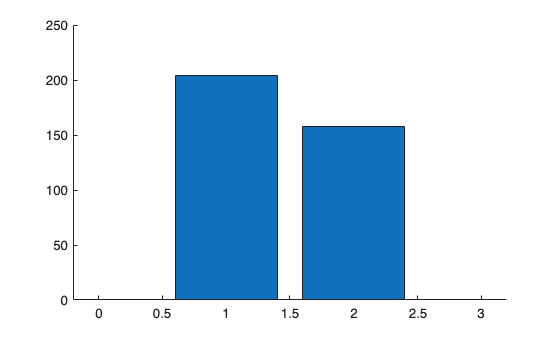


figure; hold on;
bar([mean(cellcount(1:18)), mean(cellcount(19:36))])